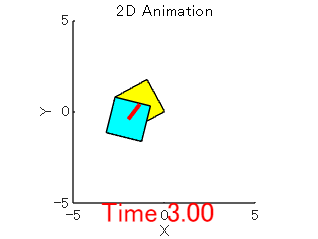

clear

% Symbolic Math Toolboxを使用して変数を宣言
syms g m a
syms theta_1(t) theta_2(t) x_1(t) y_1(t) x_2(t) y_2(t)
syms theta_dot_1(t) theta_dot_2(t) x_dot_1(t) y_dot_1(t) x_dot_2(t) y_dot_2(t)

A_1 = [x_1;
    y_1];

A_2 = [x_2;
    y_2];

q_1 = [x_1;
    y_1;
    theta_1];

q_2 = [x_2;
    y_2;
    theta_2];

q_1_dot = [x_dot_1;
    y_dot_1;
    theta_dot_1];

q_2_dot = [x_dot_2;
    y_dot_2;
    theta_dot_2];


q = formula([q_1;q_2]);
q_dot = formula([q_1_dot;q_2_dot]);

% 回転行列を定義
R_1 = [cos(theta_1), -sin(theta_1); sin(theta_1), cos(theta_1)];
R_2 = [cos(theta_2), -sin(theta_2); sin(theta_2), cos(theta_2)];

M_1 = [m 0 0;
    0 m 0;
    0 0 2/3*m*a^2];

M_2 = [m 0 0;
    0 m 0;
    0 0 2/3*m*a^2];

Q_1 = [0;
    -m*g;
    0];

Q_2 = [0;
    -m*g;
    0];

% blkdiag関数で対角ブロック行列を作成
M = blkdiag(M_1, M_2); % 4x4の対角行列
% 縦方向に結合して1つの縦ベクトルを作成
Q = formula([Q_1; Q_2]); % 4x1 縦ベクトル

% 拘束式の縦ベクトルの各部分を構築
term1 = A_1 + R_1 * [-a; -a]; % 2x1ベクトル
term2 = A_2 - A_1 + R_2 * [-a; a] - R_1 * [a; a]; % 2x1ベクトル

C = formula([term1;term2]);

% ヤコビアンを計算
C_q = jacobian(C, q);

% Cをtで微分
C_dot = diff(C, t);
replace_vars = [diff(x_1(t), t); diff(y_1(t), t); diff(theta_1(t), t); diff(x_2(t), t); diff(y_2(t), t); diff(theta_2, t)]; % 微分項
replace_with = q_dot; % 対応する変数
C_dot = subs(C_dot, replace_vars, replace_with);

% C_dotをtで微分
C_dot_dot = diff(C_dot, t);
C_dot_dot = subs(C_dot_dot, replace_vars, replace_with);

% C_qをtで微分
C_q_dot = diff(C_q, t);
C_q_dot = subs(C_q_dot, replace_vars, replace_with);

% 各要素に対するヘッセ行列を計算
gamma = cell(size(C, 1), 1); % ヘッセ行列を格納するセル配列
for i = 1:size(C, 1)
    gamma{i} = -1*formula(simplify(q_dot.' * hessian(C(i), q)* q_dot));
end

% 微分の通りの以下の式を使用すると失敗する?
% gamma = gamma - 2*C_q_dot*q_dot - C_dot_dot;

% バウムガルデ安定法
alpha = 30;
beta = 30;

gamma = gamma - 2*alpha*(C_q*q_dot + C_dot) - beta^2*C;


% 行列 M と C_q のサイズを取得
[m1, n1] = size(M);   % M のサイズ
[m2, n2] = size(C_q);  % C_q のサイズ

% 行列 A を構築
A = [M, C_q.';   % 左上と右上ブロック
     C_q, zeros(m2, m2)]; % 左下と右下ブロック

b = [Q;gamma];

% 固定値のリストを作成
valid_values = [m, a, g];
valid_data = [5, 1, 9.8];

% シンボリック変数の作成
syms q_dot_dot [m1 1]
syms lambda [m2 1]

eq = A*[q_dot_dot;lambda] == b;
eq = subs(eq,valid_values, valid_data);

% 初期値のリストを作成
q_initial_data = [1; 1; 0; 3; 1; 0];
q_dot_initial_data = [0; 0; 0; 0; 0; 0];

% シミュレーションの時間設定
dt = 0.02; % 時間刻み幅 (秒)
t_end = 3; % シミュレーション終了時間 (秒)
time_steps = 0:dt:t_end; % 時間配列

% 初期状態の設定
num_q = length(q_initial_data); % 位置変数の数
pos = zeros(num_q, length(time_steps)); % 位置を格納する配列
vel = zeros(num_q, length(time_steps)); % 速度を格納する配列

% 初期位置と速度
pos(:, 1) = q_initial_data; % 初期位置
vel(:, 1) = q_dot_initial_data; % 初期速度

% ルンゲクッタ法を用いた時間積分
for t_idx = 1:(length(time_steps) - 1)
    % 現在の位置と速度
    q_current = pos(:, t_idx);
    v_current = vel(:, t_idx);
    
    % k1
    eq_subs = subs(eq, [q;q_dot], [q_current;v_current]);
    accel_k1 = double(equationsToMatrix(lhs(eq_subs), [q_dot_dot;lambda])) \ double(rhs(eq_subs));
    accel_k1 = accel_k1(1:length(q));
    vel_k1 = v_current;
    
    % k2
    q_temp = q_current + 0.5 * dt * vel_k1;
    v_temp = v_current + 0.5 * dt * accel_k1;
    eq_subs = subs(eq, [q;q_dot], [q_temp;v_temp]);
    accel_k2 = double(equationsToMatrix(lhs(eq_subs), [q_dot_dot;lambda])) \ double(rhs(eq_subs));
    accel_k2 = accel_k2(1:length(q));
    vel_k2 = v_temp;
    
    % k3
    q_temp = q_current + 0.5 * dt * vel_k2;
    v_temp = v_current + 0.5 * dt * accel_k2;
    eq_subs = subs(eq, [q;q_dot], [q_temp;v_temp]);
    accel_k3 = double(equationsToMatrix(lhs(eq_subs), [q_dot_dot;lambda])) \ double(rhs(eq_subs));
    accel_k3 = accel_k3(1:length(q));
    vel_k3 = v_temp;
    
    % k4
    q_temp = q_current + dt * vel_k3;
    v_temp = v_current + dt * accel_k3;
    eq_subs = subs(eq, [q;q_dot], [q_temp;v_temp]);
    accel_k4 = double(equationsToMatrix(lhs(eq_subs), [q_dot_dot;lambda])) \ double(rhs(eq_subs));
    accel_k4 = accel_k4(1:length(q));
    vel_k4 = v_temp;

    % 次のステップの速度と位置を更新
    vel(:, t_idx + 1) = v_current + (dt / 6) * (accel_k1 + 2 * accel_k2 + 2 * accel_k3 + accel_k4);
    pos(:, t_idx + 1) = q_current + (dt / 6) * (vel_k1 + 2 * vel_k2 + 2 * vel_k3 + vel_k4);
end



square_size = 1; % 正方形の1辺の長さ
% アニメーションの準備
% figure;
fig = figure;
% set(fig, 'Visible', 'on');
hold on;
axis equal;
axis([-20, 20, -20, 20]/4); % 描画範囲
title('2D Animation');
xlabel('X');
ylabel('Y');

% 初期プロットの設定
square1 = fill([-1, 1, 1, -1]*square_size, [-1, -1, 1, 1]*square_size, 'yellow');
square2 = fill([-1, 1, 1, -1]*square_size, [-1, -1, 1, 1]*square_size, 'cyan');
link_line = plot([0, 0], [0, 0], 'r-', 'LineWidth', 2); % 2つの物体を繋ぐ線
time_text = text(-3.5, -5.5, '', 'FontSize', 14, 'Color', 'red'); % 時間を表示

% アニメーションループ
for t_idx = 1:length(time_steps)
    % 物体1の位置と回転
    x1 = pos(1, t_idx);
    y1 = pos(2, t_idx);
    theta1 = pos(3, t_idx);
    R1 = [cos(theta1), -sin(theta1); sin(theta1), cos(theta1)];
    square1_vertices = R1 * [-1, 1, 1, -1; -1, -1, 1, 1]*square_size + [x1; y1];
    square1.XData = square1_vertices(1, :);
    square1.YData = square1_vertices(2, :);
    
    % 物体2の位置と回転
    x2 = pos(4, t_idx);
    y2 = pos(5, t_idx);
    theta2 = pos(6, t_idx);
    R2 = [cos(theta2), -sin(theta2); sin(theta2), cos(theta2)]; % 回転行列
    square2_vertices = R2 * [-1, 1, 1, -1; -1, -1, 1, 1]*square_size + [x2; y2];
    square2.XData = square2_vertices(1, :);
    square2.YData = square2_vertices(2, :);
    
    % 2つの物体を繋ぐ線
    link_line.XData = [x1, x2];
    link_line.YData = [y1, y2];
    
    % 時間を更新
    time_text.String = sprintf('Time %.2f', time_steps(t_idx));
    
    % 描画を更新
    drawnow;
    
    % 一定時間停止（アニメーションの速度調整）
    pause(0.01);
end